Training 1/10
Training 2/10
Training 3/10
Training 4/10
Training 5/10
Training 6/10
Training 7/10
Training 8/10
Training 9/10
Training 10/10


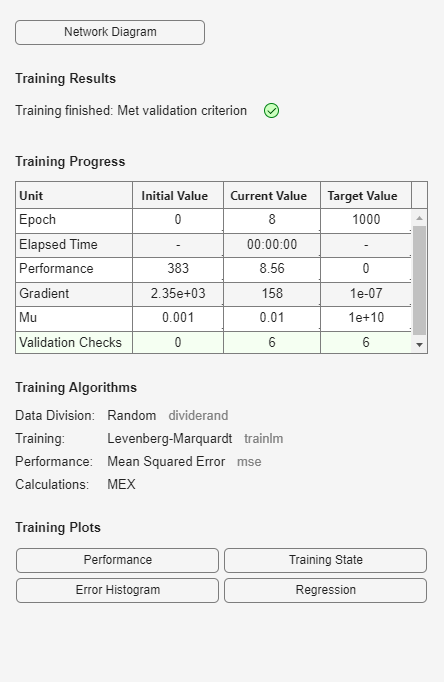

% 多个神经网络
% 提高泛化能力的另一个简单方法是训练多个神经网络并对其输出取平均值，尤其是对于含噪数据或小型数据集。
% 
% 例如，此处针对一个小问题训练 10 个神经网络，并将其均方误差与平均值的均方误差进行比较。
% 
% 首先，加载数据集并将其划分为设计集和测试集。

[x, t] = bodyfat_dataset;
Q = size(x, 2);
Q1 = floor(Q * 0.90);
Q2 = Q - Q1;
ind = randperm(Q);
ind1 = ind(1:Q1);
ind2 = ind(Q1 + (1:Q2));
x1 = x(:, ind1);
t1 = t(:, ind1);
x2 = x(:, ind2);
t2 = t(:, ind2);
% 然后，训练十个神经网络。

net = feedforwardnet(10);
numNN = 10;
nets = cell(1, numNN);
for i = 1:numNN
  fprintf('Training %d/%d\n', i, numNN)
  nets{i} = train(net, x1, t1);
end

% 接下来，基于第二个数据集对每个网络进行测试，得到单一网络性能和平均输出性能。

perfs = zeros(1, numNN);
y2Total = 0;
for i = 1:numNN
  neti = nets{i};
  y2 = neti(x2);
  perfs(i) = mse(neti, t2, y2);
  y2Total = y2Total + y2;
end
perfs

perfs =   292.2297   69.3599   72.9425   34.9048   52.0254   32.8272   54.0522   29.4749   41.7044   54.0018


y2AverageOutput = y2Total / numNN;
perfAveragedOutputs = mse(nets{1}, t2, y2AverageOutput) 

perfAveragedOutputs = 26.7045

% 平均输出的均方误差可能低于大多数单一网络的性能，但未必是全部。它可能会更好地泛化应用于其他新数据。

% 对于一些高难度问题，可以训练 100 个网络，并对任一输入取其输出的平均值。
% 这尤其适合小型含噪数据集与贝叶斯正则化训练函数 trainbr 结合使用的情况，如下所述。